# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Partie 1 : Optimisation économique

%données
demande = linspace(281,998,10) ; %choix de 10 valeurs réparties entre les productions minimale et maximale possibles
demande_bis = 400 %choix d'une demande de 400MW pour comparer les résultats avec la partie 2

demande_bis = 400


N = 5;    %nombre de variables

%fonction à minimiser
f_obj_eco = @(x) sum([A.*x.^2 + B.*x + C]) ;

%bornes
lb = Pmin ;
ub = Pmax ;

%solveur
x0 = Pmax/2 ;
Cout_optimal = zeros(length(demande),1) ;
Centrales = zeros(N,length(demande)) ;
option=optimoptions('fmincon','display','iter') ;
for k = 1:length(demande)  
    Aeq = ones(1,N) ;
    beq_eco = demande(k) ; %pour chaque valeur de demande on définit une contrainte différente
    [x_eco,fval_eco,flag_eco,output_eco]=fmincon(f_obj_eco,x0,[],[],Aeq,beq_eco,lb,ub,'',option) ; %utilisation de fmincon car fonction non linéaire
    Cout_optimal(k,1) = fval_eco ;
    Centrales(:,k) = x_eco ;
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.180e+02    5.494e+02
    1      12    2.002054e+05    2.062e+02    3.439e+02    4.001e+01
    2      18    1.339785e+05    1.198e+02    3.479e+02    4.389e+01
    3      24    1.281883e+05    1.124e+02    3.418e+02    7.819e+00
    4      30    1.279441e+05    1.121e+02    1.409e+02    3.055e-01
    5      36    1.177464e+05    9.464e+01    1.517e+02    9.417e+00
    6      42    1.176866e+05    9.454e+01    1.518e+02    6.433e-02
    7      48    1.090356e+05    7.904e+01    1.452e+02    1.216e+01
    8      54    1.052703e+05    7.028e+01    1.812e+02    6.183e+00
    9      60    8.584304e+04    8.748e+00    5.172e+01    4.651e+01
   10      66    8.415774e+04    6.350e-01    1.145e+01    8.500e+00
   11      72    8.410961e+04    4.091e-01    8.492e+00    6.923e-01
   12      78    8.410911e+04    4.065e-01    2

%Calcul pour demande = 400
beq_400 = demande_bis;
[x_400,fval_400,flag_400,output_400]=fmincon(f_obj_eco,x0,[],[],Aeq,beq_400,lb,ub,'');


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


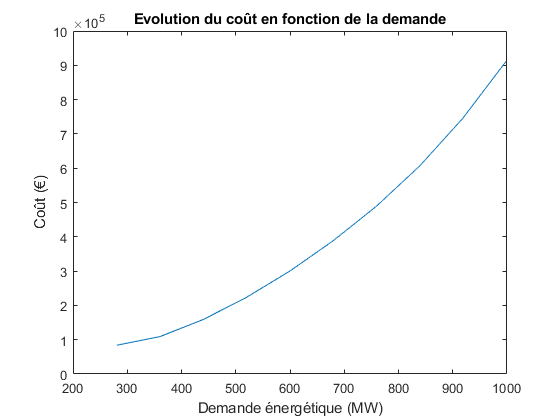

% tracé du coût en fonction de la demande
plot(demande,Cout_optimal)
xlabel('Demande énergétique (MW)')
ylabel('Coût (€)')
title('Evolution du coût en fonction de la demande')

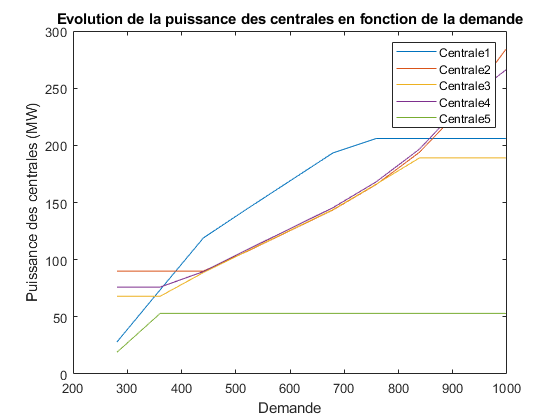

% tracé de la puissance des centrales en fonction de la demande
plot(demande,Centrales)
xlabel('Demande');
ylabel('Puissance des centrales (MW)');
title('Evolution de la puissance des centrales en fonction de la demande');
legend('Centrale1','Centrale2','Centrale3','Centrale4','Centrale5');

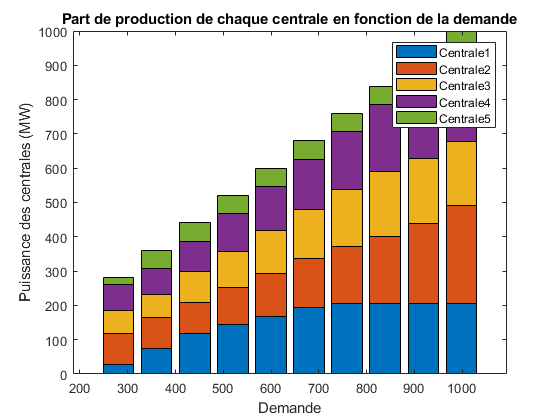

%Diagramme de la part de production de chaque centrale pour chaque valeur de demande
bar(demande,Centrales,'stacked')
xlabel('Demande');
ylabel('Puissance des centrales (MW)');
title('Part de production de chaque centrale en fonction de la demande');
legend('Centrale1','Centrale2','Centrale3','Centrale4','Centrale5');

## Partie 2 : Optimisation environmentale

%fonction à minimiser
f_obj_env = @(x) sum([(D/24).*x.^2 + (E/24).*x + F]) ; %On convertit D et E en kg/h en divisant par 24

%contraintes
beq_env = demande_bis ;

%bornes
lb = Pmin ;
ub = Pmax ;

%solveur : fmincon car la fonction objectif n'est pas linéaire
x0_env = Pmax/2 ;
option=optimoptions('fmincon','display','iter') ;
[x_env,fval_env,flag_env,output_env]=fmincon(f_obj_env,x0_env,[],[],Aeq,beq_env,lb,ub,'',option) ;

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    6.814161e+03    9.900e+01    2.078e+01
    1      12    4.449298e+03    2.417e+01    1.738e+01    4.205e+01
    2      18    4.432529e+03    2.383e+01    1.733e+01    4.660e-01
    3      24    3.884607e+03    1.549e+01    1.478e+01    2.292e+01
    4      30    3.879549e+03    1.524e+01    5.797e+00    1.566e-01
    5      36    3.670438e+03    0.000e+00    2.087e+00    1.220e+01
    6      42    3.658064e+03    0.000e+00    1.370e+00    6.294e+00
    7      48    3.654624e+03    0.000e+00    2.862e-01    5.445e+00
    8      54    3.654479e+03    0.000e+00    2.467e-01    3.764e-01
    9      60    3.654191e+03    0.000e+00    6.958e-02    1.605e+00
   10      66    3.654169e+03    5.684e-14    1.282e-03    5.641e-01
   11      72    3.654169e+03    0.000e+00    1.124e-04    4.428e-03
   12      78    3.654169e+03    0.000e+00    8

%Affichage des résultas
disp('production d''éléctricité de chaque centrale qui minimise les rejets de polluants')

production d'éléctricité de chaque centrale qui minimise les rejets de polluants


disp(x_env)

   71.6220
   90.0000
   68.0000
  129.7628
   40.6152



disp('quantité totale de polluants produits')

quantité totale de polluants produits


disp(fval_env)

   3.6542e+03



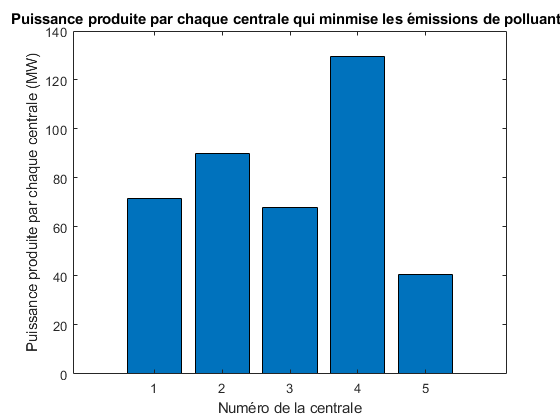

%Diagramme de la puissance produite par chaque centrale
abscisse = [1 2 3 4 5];
bar(abscisse,x_env)
xlabel('Numéro de la centrale');
ylabel('Puissance produite par chaque centrale (MW)');
title('Puissance produite par chaque centrale qui minmise les émissions de polluants');

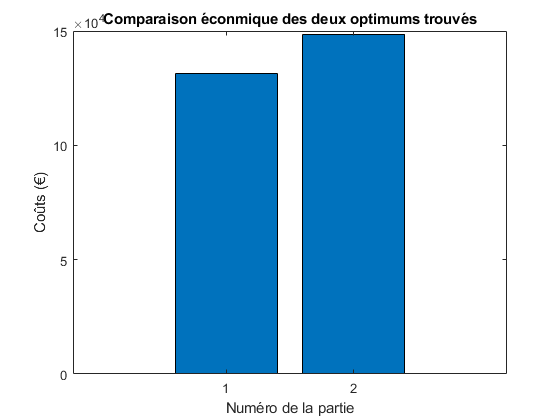

%Comparaison des optimums environmental et économique

bar([1 2],[fval_400,f_obj_eco(x_env)])
xlabel('Numéro de la partie');
ylabel('Coûts (€)');
title('Comparaison éconmique des deux optimums trouvés');

disp('Comme on pouvait s''y attendre,le coût est inférieur lorsqu''on privilégie l''aspect éconmique')

Comme on pouvait s'y attendre,le coût est inférieur lorsqu'on privilégie l'aspect éconmique


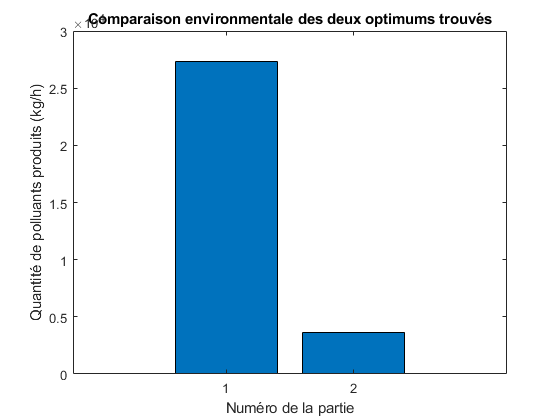


bar([1 2],[f_obj_env(x_eco),fval_env])
xlabel('Numéro de la partie');
ylabel('Quantité de polluants produits (kg/h)');
title('Comparaison environmentale des deux optimums trouvés');

disp('Comme on pouvait s''y attendre, privilégier l''aspect environmental réduit très fortement la quantité de polluants produits')

Comme on pouvait s'y attendre, privilégier l'aspect environmental réduit très fortement la quantité de polluants produits


## Partie 3 : Optimisation multicritère

%Méthode de pondération

%données
w = linspace(0,1,50) ; %choix de 50 valeurs de pondération
taxe = mean([0.1,0.5]*24);

%fonction objectif
fobj_eco_bis =  @(x) (f_obj_eco(x) + f_obj_env(x)*taxe) ; %prise en compte de la taxe environmentale dans une nouvelle fonction économique

%contraintes
beq_multi = demande_bis ;

%solveur
sol_multi = zeros(N,length(w));
fsol_multi = zeros(2,length(w));
valeur_multi = zeros(1,length(w));
option=optimoptions('fmincon','display','iter') ;

for k = 1:length(w)
    fw = @(x) w(k)*fobj_eco_bis(x) + (1-w(k))*f_obj_env(x) ;
    [x_multi,fval_multi,flag_multi,output_multi]=fmincon(fw,x0,[],[],Aeq,beq_multi,lb,ub,@(x) contraintes_NL(x,D,E,F),option) ;
    sol_multi(:,k) = x_multi ;
    valeur_multi(1,k) = fval_multi;
    fsol_multi(1,k) = fobj_eco_bis(x_multi) ;
    fsol_multi(2,k) = f_obj_env(x_multi) ;
    
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    6.814161e+03    9.900e+01    2.080e+01
    1      12    4.587549e+03    2.398e+01    1.793e+01    3.919e+01
    2      18    4.570461e+03    2.363e+01    1.789e+01    4.469e-01
    3      24    3.859859e+03    1.389e+01    1.274e+01    2.917e+01
    4      30    3.855482e+03    1.373e+01    4.233e+00    1.502e-01
    5      36    3.673779e+03    5.684e-14    3.498e+00    9.799e+00
    6      42    3.661381e+03    0.000e+00    1.841e+00    5.362e+00
    7      49    3.654693e+03    0.000e+00    3.479e-01    7.544e+00
    8      55    3.654535e+03    0.000e+00    2.684e-01    3.968e-01
    9      61    3.654199e+03    5.684e-14    8.070e-02    1.689e+00
   10      67    3.654169e+03    0.000e+00    7.364e-04    6.707e-01
   11      73    3.654169e+03    0.000e+00    4.816e-05    2.429e-03
   12      79    3.654169e+03    0.000e+00    5

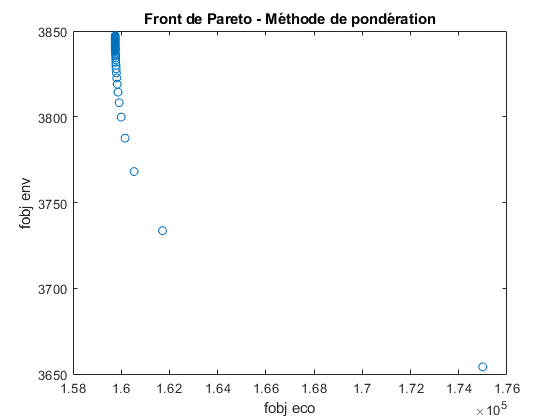

% Tracé du front de Pareto
plot(fsol_multi(1,:),fsol_multi(2,:),'O')
xlabel('fobj eco');
ylabel('fobj env');
title('Front de Pareto - Méthode de pondération')

%Méthode du but à atteindre

%données
%L'objectif est définit grâce aux optimums trouvés en parties 1 et 2
goal = [fval_400,fval_env];

%fonction objectif
fun = @(x) [f_obj_eco(x)
    f_obj_env(x)] ;

%solveur
options = optimoptions('fgoalattain','Display','iter')

options =   fgoalattain options:

   Set properties:
                      Display: 'iter'

   Default properties:
          ConstraintTolerance: 1.0000e-06
            EqualityGoalCount: 0
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
            FunctionTolerance: 1.0000e-06
       MaxFunctionEvaluations: '100*numberOfVariables'
                MaxIterations: 400
          OptimalityTolerance: 1.0000e-06
                    OutputFcn: []
                      PlotFcn: []
    SpecifyConstraintGradient: 0
     SpecifyObjectiveGradient: 0
                StepTolerance: 1.0000e-06
                     TypicalX: 'ones(numberOfVariables,1)'
                  UseParallel: 0


sol_goal = zeros(N,length(w));
fsol_goal = zeros(2,length(w));
gamma = zeros(1,length(w));
for k = 1:length(w)
    weight = [w(k),1-w(k)] ;
    [x_goal,fval_goal,factor,flag_goal,output_goal]=fgoalattain(fun,x0,goal,weight,[],[],Aeq,beq_multi,lb,ub,@(x) contraintes_NL(x,D,E,F),options) ;
    sol_goal(:,k) = x_goal ;
    gamma(1,k) = factor; 
    valeur_goal(:,k) = fval_goal;
    fsol_goal(:,k) = fval_goal;
end


                 Attainment        Max     Line search     Directional 
 Iter F-count        factor    constraint   steplength      derivative   Procedure 
    0      7              0        101357                                            
    1     15           -463     1.412e+04            1          -0.992     
    2     23        -0.0917          3118            1           0.998     
    3     31          150.2         868.4            1           0.995     
    4     39          244.4         313.7            1           0.995     
    5     47          293.7         143.5            1           0.992     
    6     55          315.4         85.12            1           0.974     
    7     63          339.1         35.71            1           0.991     
    8     71          357.9         15.97            1           0.994     
    9     79          365.5         9.311            1           0.977     
   10     87          372.3         4.449            1           0.987   

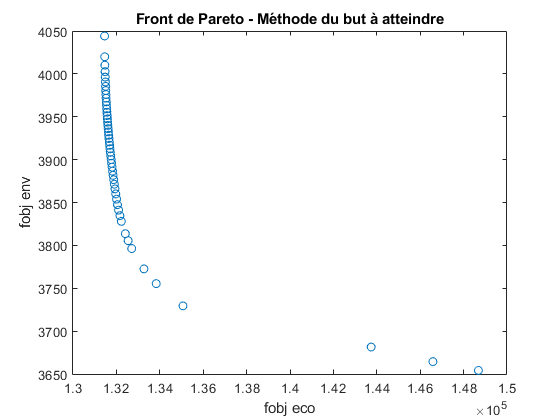

%Tracé du front de Pareto
plot(fsol_goal(1,:),fsol_goal(2,:),'O')
xlabel('fobj eco');
ylabel('fobj env');
title('Front de Pareto - Méthode du but à atteindre');

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

%résultats avec la méthode de pondération
xx_multi = find(valeur_multi == min(valeur_multi));
disp('optimum trouvé');

optimum trouvé


disp(sol_multi(:,xx_multi));

   71.6220
   90.0000
   68.0000
  129.7628
   40.6152



disp('coût correspondant');

coût correspondant


disp(fsol_multi(1,xx_multi));

   1.7499e+05



disp('quantité de poluants correspondant');

quantité de poluants correspondant


disp(fsol_multi(2,xx_multi));

   3.6542e+03



%résultats avec la méthode du but à atteindre
xx_goal = find(gamma == min(gamma(find(gamma >=0))));
disp('optimum trouvé');

optimum trouvé


disp(sol_goal(:,xx_goal));

  103.0368
   90.0000
   75.2705
   78.6927
   53.0000



disp('coût correspondant');

coût correspondant


disp(fsol_goal(1,xx_goal));

   1.3147e+05



disp('quantité de poluants correspondant');

quantité de poluants correspondant


disp(fsol_goal(2,xx_goal));

   4.0102e+03



%Les deux méthodes renvoient des résultats différents. La méthode de
%pondération renvoit un meilleur résultat environmental et la méthode du but à
%atteindre renvoit un meilleur résultat éconmique

function [cineq,ceq] = contraintes_NL(x,D,E,F)
    polution_max = mean([90000,95000]/24) ;
    cineq = (D/24).*x.^2+(E/24).*x+ F - polution_max ;
    ceq = [] ;
end